# **디지털신호처리 ****HW#1**

Due date : 2021.10.21. 23:59

**이름**** : 김지원        **

**학번**** : 201716155**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : **

**https://github.com/KimJiWon0/peace**

1. 다음 신호를 stem 함수를 이용하여 그려라.

1) 

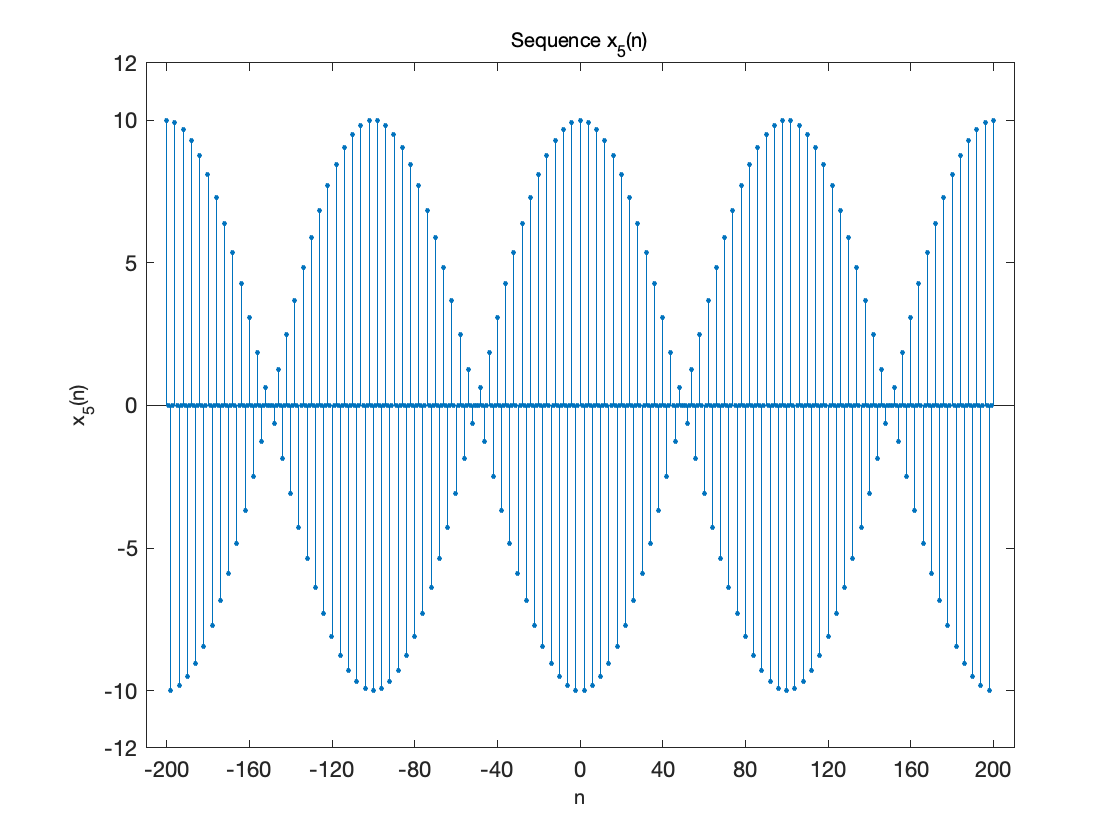

n5 = [-200:200];
x5 = 5*(cos(0.49*pi*n5) + cos(0.51*pi*n5));

Hf_1 = figure; 
set(Hf_1, 'NumberTitle' ,'off','Name','P0201e');
Hs = stem(n5,x5,'filled');
set(Hs,'markersize',2);
axis([min(n5)-10,max(n5)+10,min(x5)-2,max(x5)+2]);
xlabel('n','FontSize',10);
ylabel('x_5(n)','FOntSize',10); 
title('Sequence x_5(n)','FontSize',10);
ntick = [n5(1): 40:n5(end)]; ytick = [-12 -10:5:10 12]; 
set(gca,'XTickMode','manual','XTick',ntick);
set(gca,'YTickMode','manual','YTick',ytick);

2) 

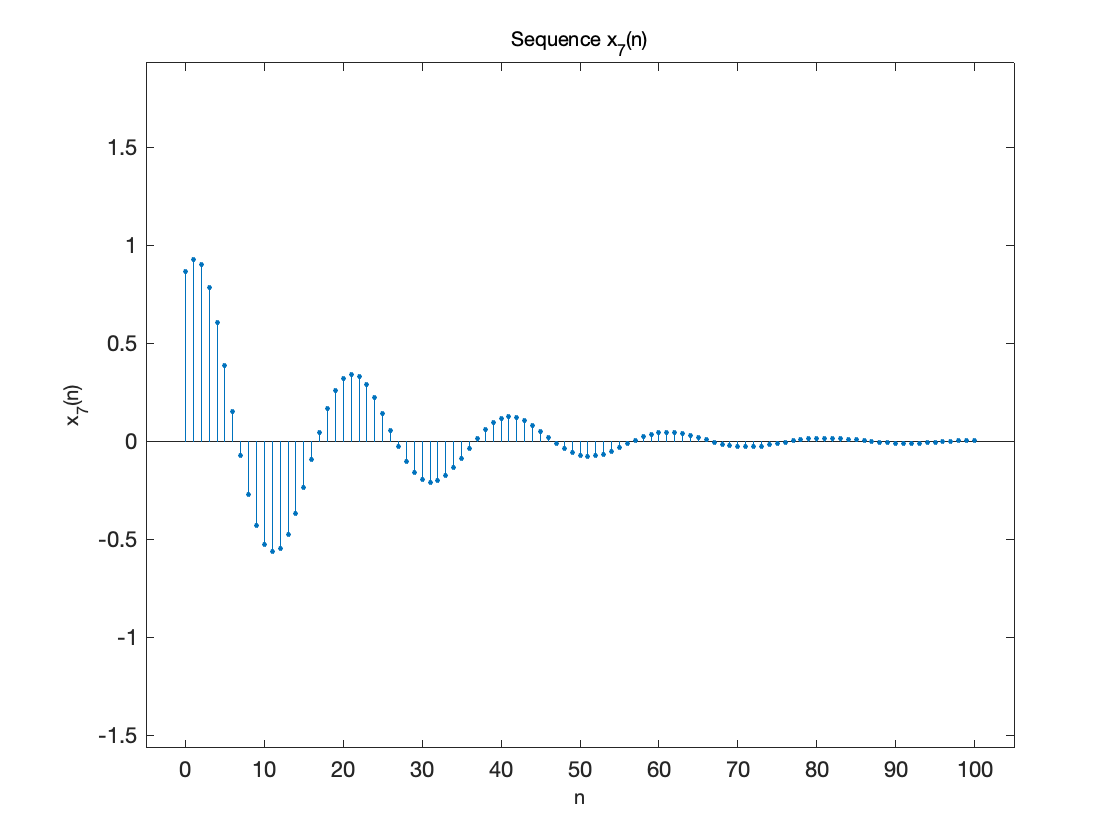


n7 = [0:100];
x7 = exp(-0.05*n7).*sin(0.1*pi*n7 + pi/3);

Hf_1 = figure;
set(Hf_1,'NumberTitle','off','Name','P0201g');
Hs = stem(n7,x7,'filled');
set(Hs,'markersize',2);
axis([min(n7)-5,max(n7)+5,min(x7)-1,max(x7)+1]);
xlabel('n','FontSize',10);
ylabel('x_7(n)','FontSize',10);
title('Sequence x_7(n)','FontSize',10);
ntick = [n7(1): 10:n7(end)];
set(gca,'XTickMode','manual','XTick',ntick);

2.  (P2.16) LTI 시스템의 차분 방정식이 다음과 같다.


$$y\left(n\right)-0\ldotp 5y\left(n-1\right)+0\ldotp 25y\left(n-2\right)=x\left(n\right)+2x\left(n-1\right)+x\left(n-3\right)$$


1) MATLAB의 impz 함수를 사용하여 0<=n<=100 구간에서 시스템의 임펄스 응답을 구하고 stem을 이용해서 그려라.

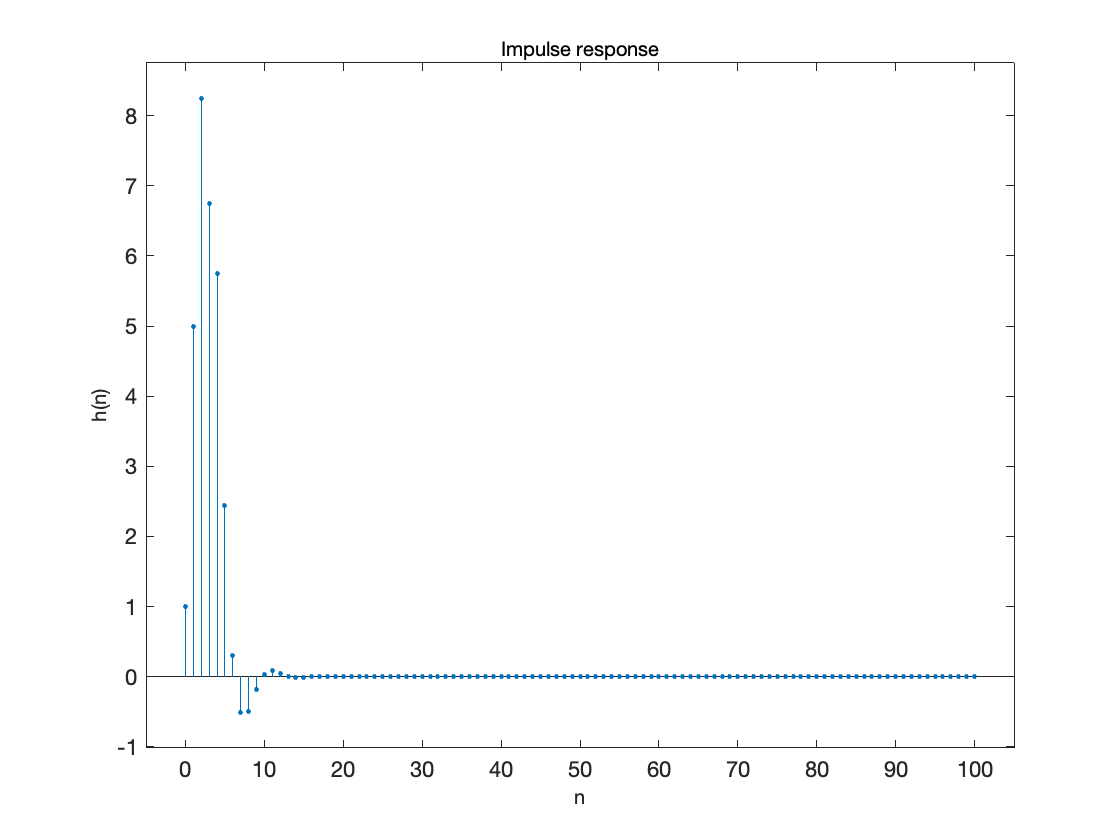

b = [1 2 0 1]; a = [1 -0.5 0.25]; n = [0:100];
[delta,n] = impz(b,a,n);
h = filter(b,a,delta);
Hf_1 = figure;
set(Hf_1,'NumberTitle','off','Name','P0219a');
Hs = stem(n,h,'filled');
set(Hs,'markersize',2);
axis([min(n)-5,max(n)+5,min(h)-0.5,max(h)+0.5]);
xlabel('n','FontSize',10); ylabel('h(n)','FontSize',10); 
title('Impulse response','FontSize',10);

2) 이 임펄스 응답으로부터 안정성을 판별하라. (sum, abs 함수 사용)

a = sum(abs(h))

a = 30.8577

% h = if  can write as a real number, a is a stable thing.

3) 만약 이 시스템의 입력이  이면, filter 함수를 사용하여0<=n<=200 구간에서 응답 y(n)을 구하라.

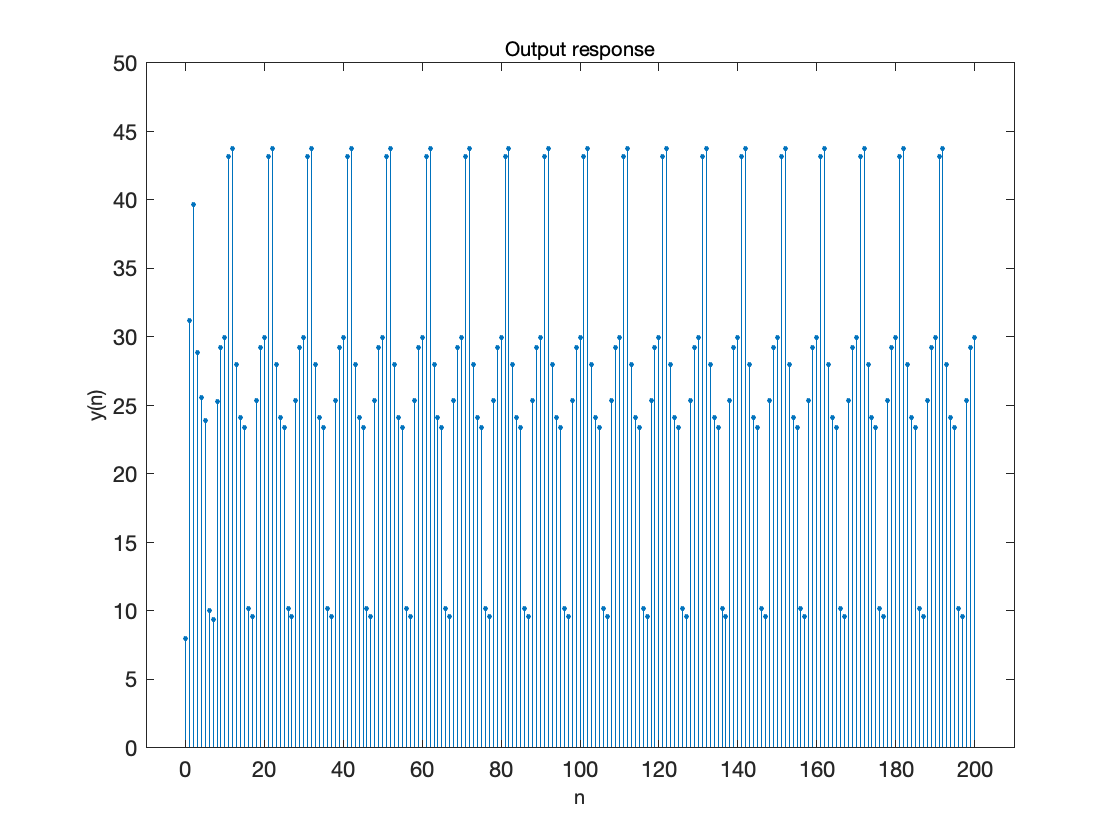

b = [1 2 0 1]; a = [1 -0.5 0.25]; n = 0:200;
x = 5*ones(size(n))+3*cos(0.2*pi*n)+4*sin(0.6*pi*n); y = filter(b,a,x);
Hf_1 = figure;
set(Hf_1,'NumberTitle','off','Name','P0219c');
Hs = stem(n,y,'filled');
set(Hs,'markersize',2); 
axis([-10,210,0,50]);
xlabel( 'n','FontSize',10); ylabel('y(n)','FontSize',10);
title('Output response','FontSize',10);

3. (P2.20) 

일 때, 다음을 그려라. 

1) y(n)의 처음 51개 샘플을 stem 함수 이용해서 그려라. 

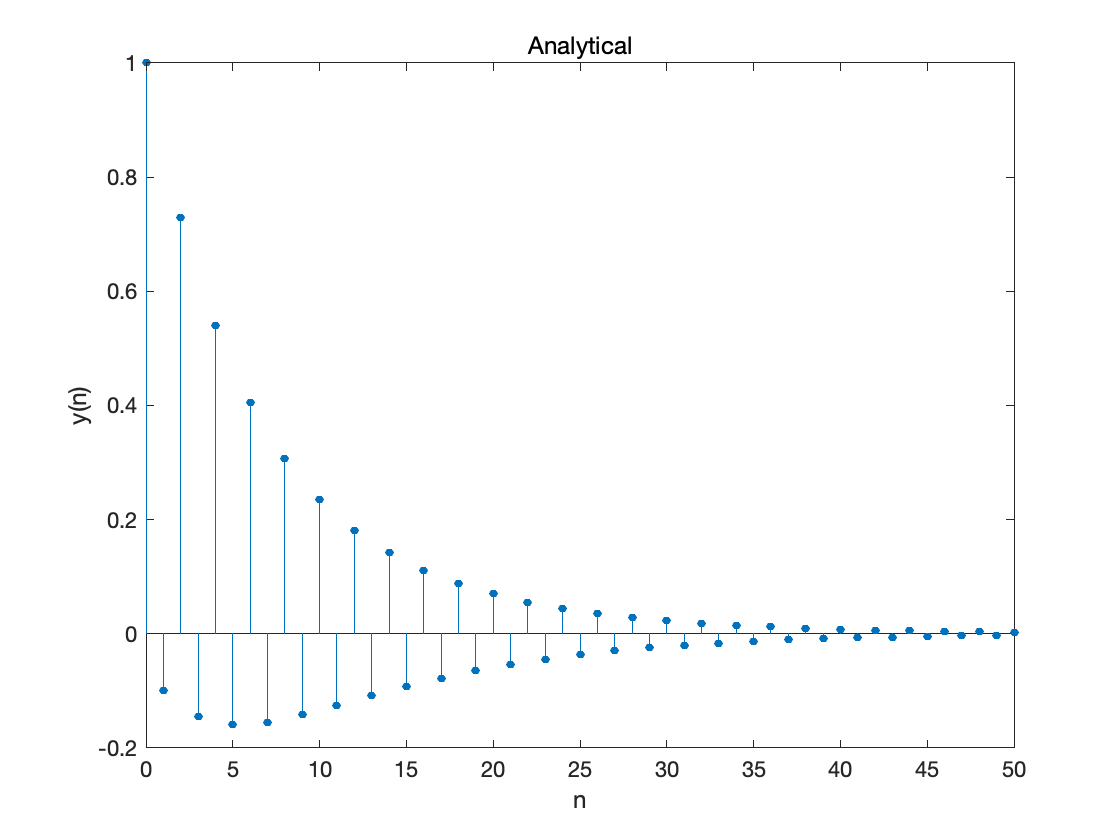

n = [0:50]; x = 0.8.^n; h = (-0.9).^n;
Hf_1 = figure;
set(Hf_1,'NumberTitle','off','Name','P0216');
y1 = ((0.8).^(n+1) - (-0.9).^(n+1))/(0.8+0.9);
subplot(1,1,1);
Hs1 = stem(n,y1,'filled');
set(Hs1,'markersize',4);
title('Analytical'); xlabel('n'); ylabel('y(n)');

2) x(n)과 h(n)을 26개의 샘플이 되도록 자른뒤, conv 함수를 이용해서 y(n)을 구하고 stem 이용해서 그려라. 

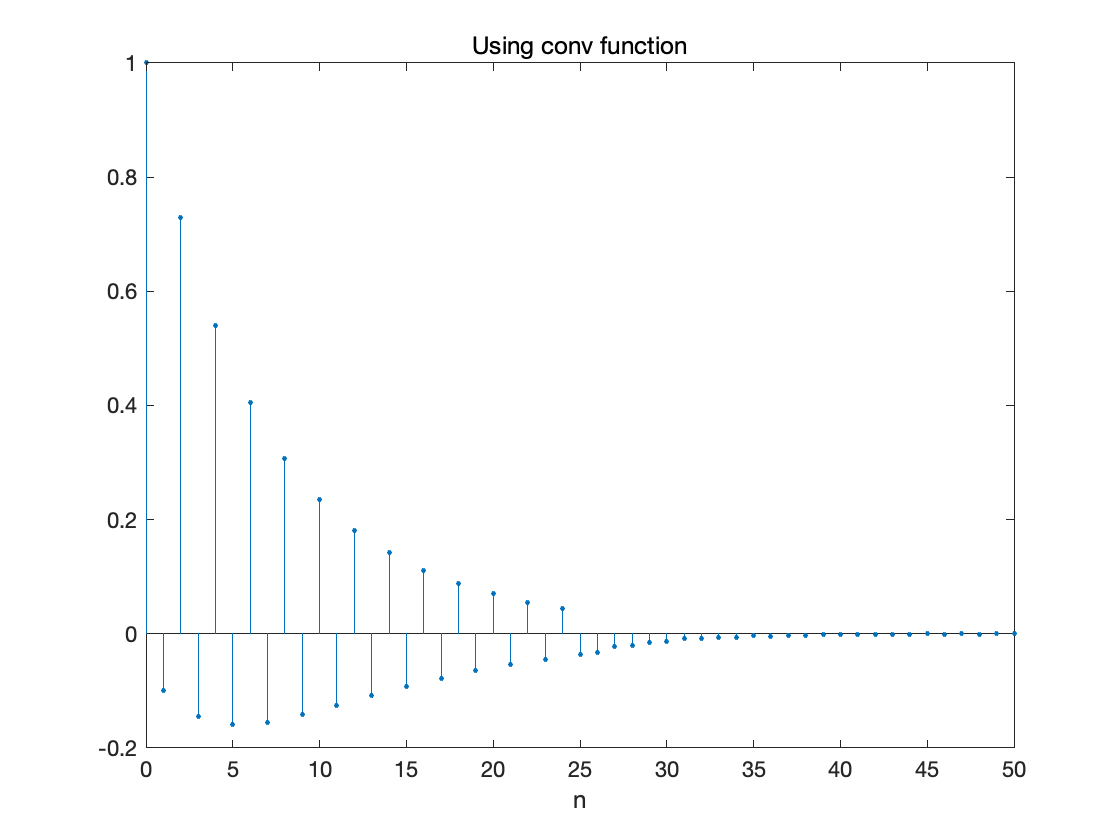

x2 = x(1:26); h2 = h(1:26); y2 = conv(h2,x2);
subplot(1,1,1);
Hs2 = stem(n,y2,'filled');
set(Hs2,'markersize',2); 
title('Using conv function');
xlabel('n');

3) filter 함수를 이용해서 $x\left(n\right)\ast h\left(n\right)$의 처음 51개 샘플을 구하고 stem 이용해서 그려라. 

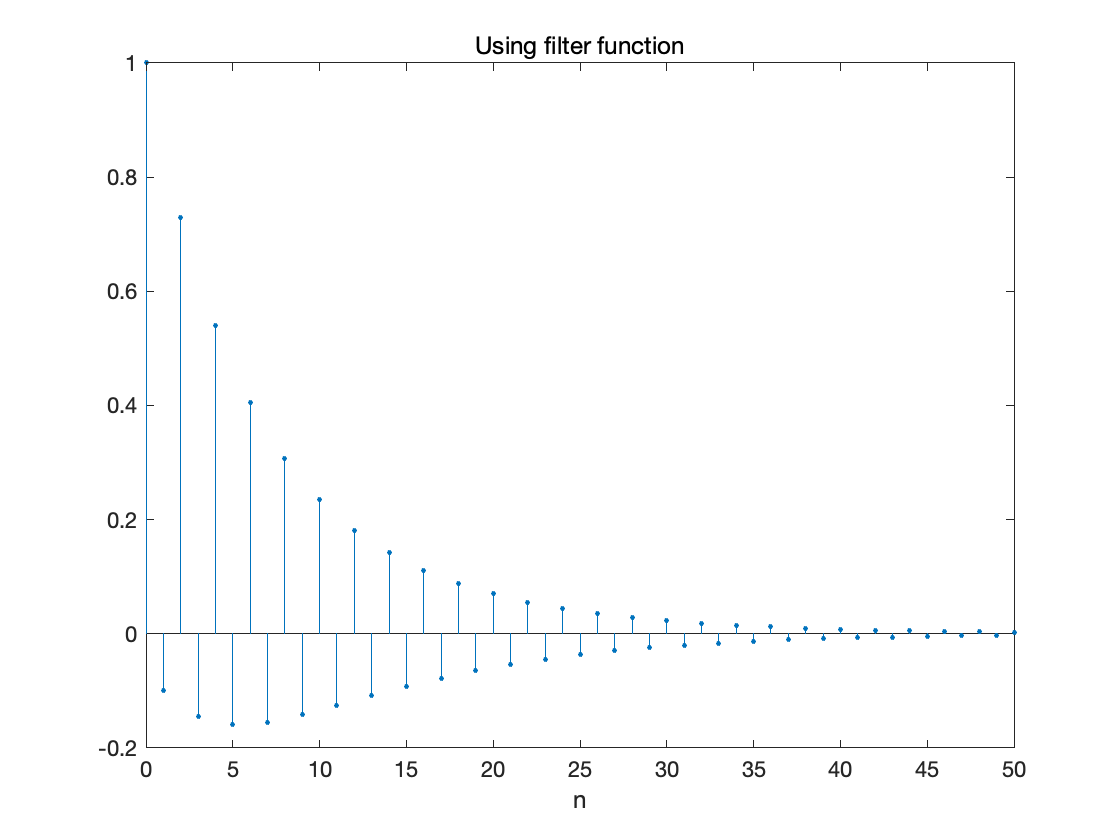


y3 = filter([1],[1,0.9],x);
subplot(1,1,1); Hs3 = stem(n,y3,'filled');
set(Hs3,'markersize',2);
title('Using filter function');
xlabel('n');

4. (P3.14) 임펄스 응답으로 기술된 각 선형 시불변 시스템에 대해 구간 $\left\lbrack -\pi ,\pi \right\rbrack$에서 주파수 응답 함수 $H\left(e^{j\omega } \right)$을 구하고 크기 응답과 위상 응답을 그려라. 

1) $h\left(n\right)={\left(0\ldotp 9\right)}^{|n|}$

w = [0:1:200]*pi/200;
H = exp(j*w) ./ (exp(j*w) -0.9*ones(1,201))

H =   10.0000 + 0.0000i   9.7936 - 1.3829i   9.2250 - 2.5964i   8.4178 - 3.5335i   7.5101 - 4.1700i   6.6098 - 4.5414i   5.7812 - 4.7084i   5.0519 - 4.7321i   4.4267 - 4.6624i   3.8980 - 4.5359i   3.4539 - 4.3777i   3.0813 - 4.2044i   2.7682 - 4.0265i   2.5043 - 3.8505i   2.2807 - 3.6800i   2.0904 - 3.5173i   1.9275 - 3.3632i   1.7873 - 3.2181i   1.6661 - 3.0820i   1.5606 - 2.9544i   1.4684 - 2.8351i   1.3875 - 2.7234i   1.3160 - 2.6188i   1.2528 - 2.5208i   1.1965 - 2.4289i   1.1462 - 2.3427i   1.1011 - 2.2616i   1.0606 - 2.1854i   1.0240 - 2.1135i   0.9908 - 2.0457i   0.9607 - 1.9816i   0.9334 - 1.9211i   0.9083 - 1.8637i   0.8855 - 1.8092i   0.8645 - 1.7576i   0.8451 - 1.7085i   0.8273 - 1.6617i   0.8109 - 1.6172i   0.7957 - 1.5747i   0.7816 - 1.5341i   0.7685 - 1.4953i   0.7564 - 1.4582i   0.7450 - 1.4227i   0.7344 - 1.3887i   0.7245 - 1.3560i   0.7153 - 1.3246i   0.7066 - 1.2944i   0.6985 - 1.2654i   0.6908 - 1.2375i   0.6836 - 1.2106i


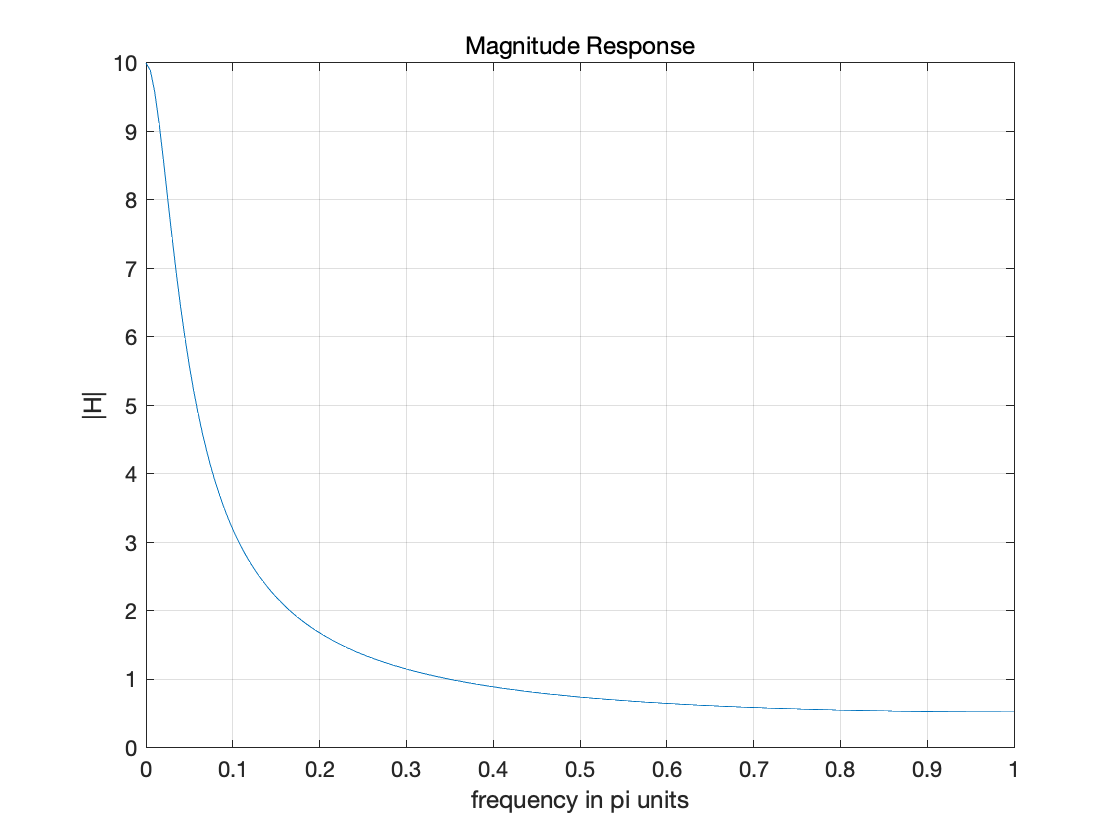

magH = abs(H); angH = angle(H);
subplot(1,1,1); plot(w/pi,magH); grid;
xlabel('frequency in pi units'); ylabel('|H|');
title('Magnitude Response');

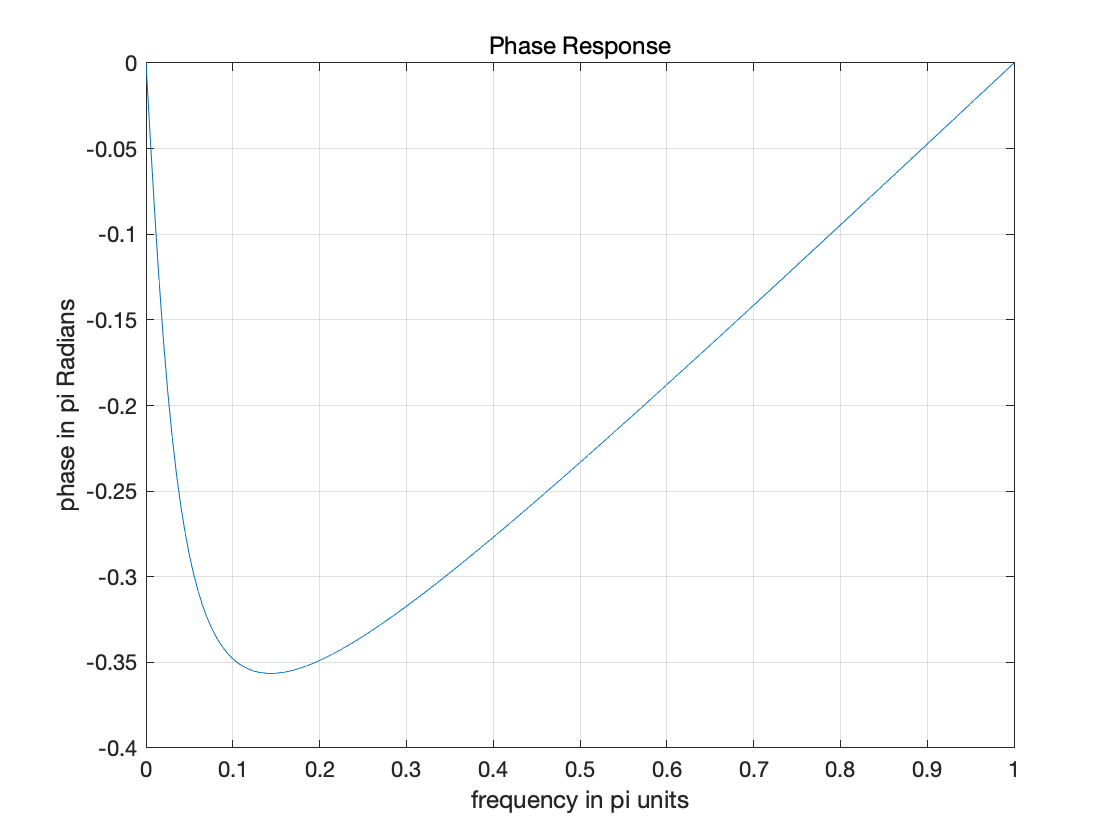


subplot(1,1,1); plot(w/pi,angH/pi); grid;
xlabel('frequency in pi units'); ylabel('phase in pi Radians');
title('Phase Response');

2) $h\left(n\right)=\left\lbrack {\left(0\ldotp 5\right)}^n +{\left(0\ldotp 4\right)}^n \right\rbrack u\left(n\right)$

w = [0:1:200]*pi/200;
H = [exp(j*w) ./ (exp(j*w) -0.4*ones(1,201)) + exp(j*w) ./ (exp(j*w) -0.5*ones(1,201))]

H =    3.6667 + 0.0000i   3.6656 - 0.0488i   3.6624 - 0.0976i   3.6572 - 0.1460i   3.6498 - 0.1941i   3.6405 - 0.2416i   3.6291 - 0.2885i   3.6158 - 0.3346i   3.6007 - 0.3799i   3.5838 - 0.4241i   3.5652 - 0.4674i   3.5450 - 0.5094i   3.5232 - 0.5503i   3.5001 - 0.5898i   3.4756 - 0.6280i   3.4499 - 0.6648i   3.4231 - 0.7001i   3.3952 - 0.7340i   3.3665 - 0.7664i   3.3369 - 0.7972i   3.3066 - 0.8265i   3.2757 - 0.8543i   3.2443 - 0.8806i   3.2125 - 0.9053i   3.1802 - 0.9286i   3.1478 - 0.9504i   3.1151 - 0.9708i   3.0823 - 0.9897i   3.0494 - 1.0073i   3.0166 - 1.0235i   2.9838 - 1.0384i   2.9511 - 1.0520i   2.9186 - 1.0645i   2.8863 - 1.0757i   2.8543 - 1.0858i   2.8226 - 1.0948i   2.7912 - 1.1028i   2.7602 - 1.1097i   2.7295 - 1.1157i   2.6992 - 1.1208i   2.6694 - 1.1250i   2.6401 - 1.1283i   2.6111 - 1.1309i   2.5827 - 1.1327i   2.5547 - 1.1337i   2.5273 - 1.1341i   2.5003 - 1.1339i   2.4738 - 1.1330i   2.4478 - 1.1316i   2.4224 - 1.1296i


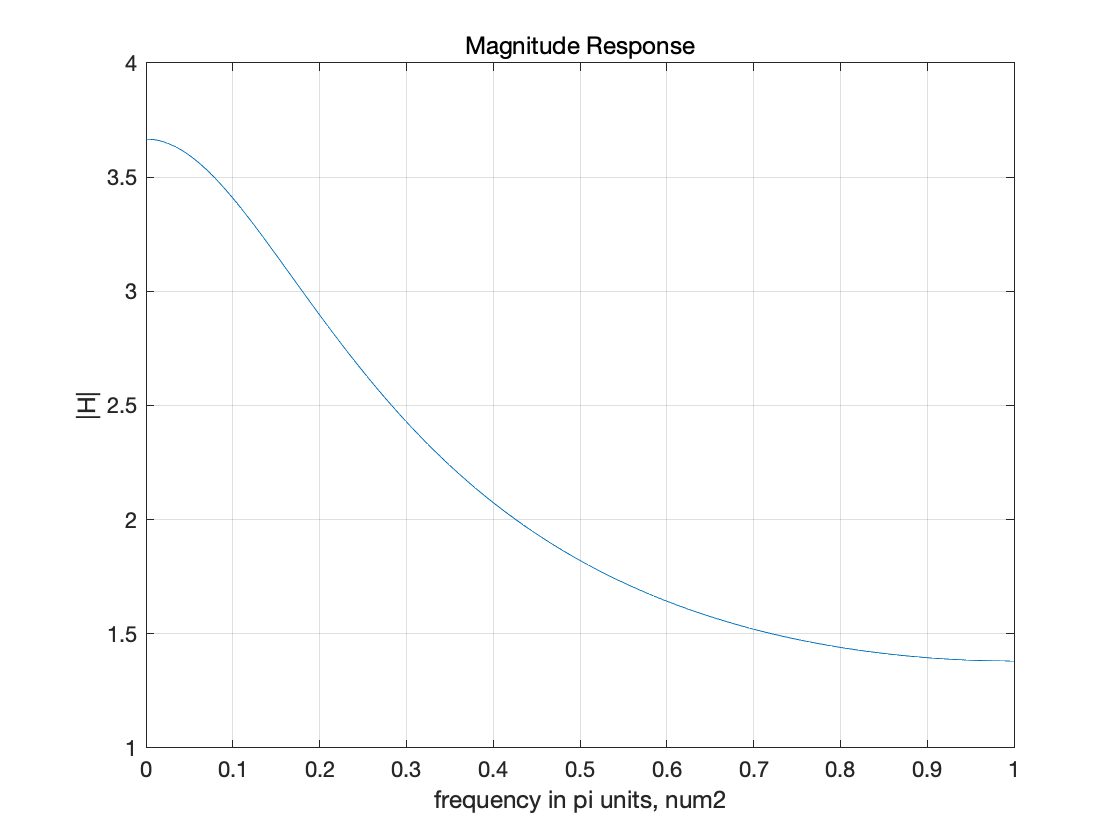

magH = abs(H); angH = angle(H);
subplot(1,1,1); plot(w/pi,magH); grid;
xlabel('frequency in pi units, num2'); ylabel('|H|');
title('Magnitude Response');

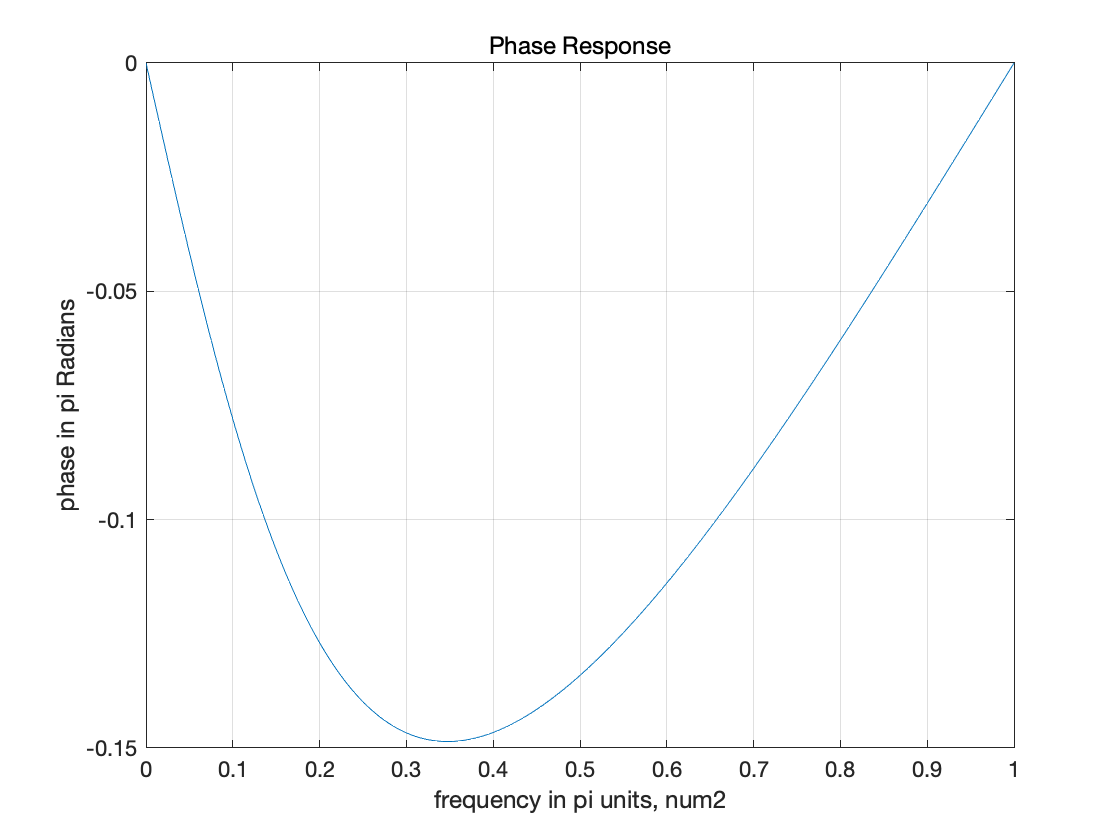

subplot(1,1,1); plot(w/pi,angH/pi); grid;
xlabel('frequency in pi units, num2'); ylabel('phase in pi Radians');
title('Phase Response');

5. (P3.17) 

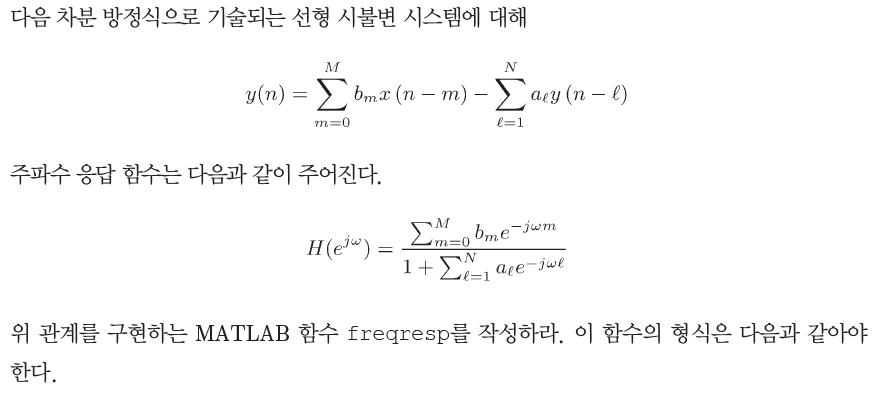


b= reshape(b,1,length(b));
a= reshape(a,1,length(a));
w= reshape(w,1,length(w));
m= 0:length(b)-1; 
num = b*exp(-j*m'*w); 
l= 0:length(a)-1;
den = a*exp(-j*l'*w);
H = num./den;

6. (P3.19) 다음의 각 시스템에 대해 $H\left(e^{j\omega } \right)$을 구하고, 그 크기와 위상을 그려라

1) $y\left(n\right)=x\left(n\right)-x\left(n-2\right)+0\ldotp 95y\left(n-1\right)-0\ldotp 9025y\left(n-2\right)$

w = [-300:300]*pi/300; 
a = [1 -0.95 0.9025]; 
b = [1 0 -1]; 
H = num./den;
H

H =   -0.0000 + 0.0000i   0.0000 + 0.0073i   0.0000 + 0.0147i   0.0000 + 0.0220i   0.0000 + 0.0294i   0.0001 + 0.0367i   0.0001 + 0.0441i   0.0001 + 0.0514i   0.0002 + 0.0588i   0.0002 + 0.0662i   0.0003 + 0.0736i   0.0003 + 0.0809i   0.0004 + 0.0883i   0.0004 + 0.0957i   0.0005 + 0.1032i   0.0006 + 0.1106i   0.0007 + 0.1180i   0.0008 + 0.1255i   0.0009 + 0.1329i   0.0010 + 0.1404i   0.0011 + 0.1479i   0.0012 + 0.1554i   0.0013 + 0.1630i   0.0014 + 0.1705i   0.0015 + 0.1781i   0.0017 + 0.1857i   0.0018 + 0.1933i   0.0020 + 0.2009i   0.0021 + 0.2086i   0.0023 + 0.2162i   0.0024 + 0.2239i   0.0026 + 0.2317i   0.0028 + 0.2394i   0.0030 + 0.2472i   0.0032 + 0.2550i   0.0034 + 0.2629i   0.0036 + 0.2707i   0.0038 + 0.2786i   0.0040 + 0.2866i   0.0042 + 0.2946i   0.0045 + 0.3026i   0.0047 + 0.3106i   0.0050 + 0.3187i   0.0052 + 0.3268i   0.0055 + 0.3350i   0.0057 + 0.3432i   0.0060 + 0.3514i   0.0063 + 0.3597i   0.0066 + 0.3680i   0.0069 + 0.3764i


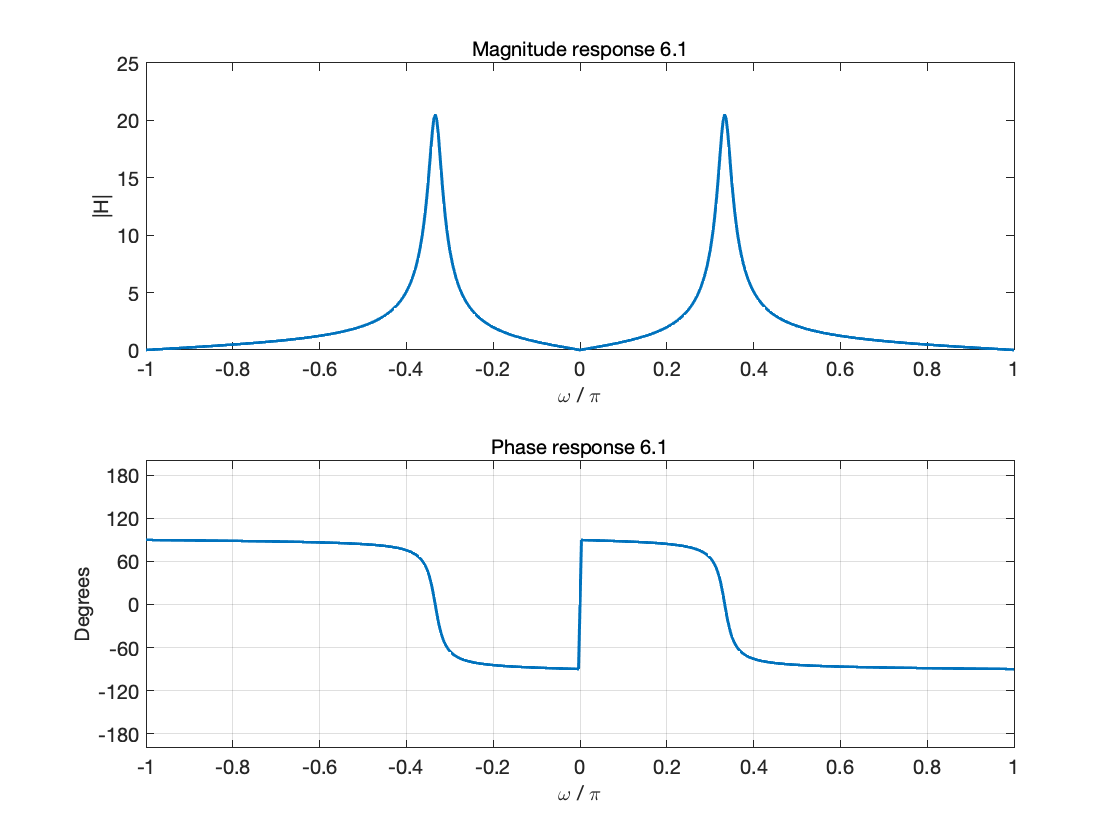

magH = abs(H); phaH = angle(H)*180/pi;
Hf_1 = figure; 
set(Hf_1,'NumberTitle','off','Name','P0317b');
subplot(2,1,1); plot(w/pi,magH,'LineWidth',1.5);
axis([-1 1 0 25]);
wtick = [-1:0.2:1]; 
magtick = [0:5:25];
xlabel( '\omega / \pi','FontSize',10); ylabel('|H|','FontSize',10);
title(['Magnitude response 6.1'],'FontSize',10);
set(gca,'XTick',wtick); set(gca,'YTick',magtick);
subplot(2,1,2); plot(w/pi,phaH,'LineWidth',1.5); grid;
axis([-1 1 -200 200]);
wtick = [-1:0.2:1];
magtick = [-180:60:180];
xlabel('\omega / \pi','FontSize',10); ylabel('Degrees','FontSize',10); 
title(['Phase response 6.1'],'FontSize',10);
set(gca,'XTick',wtick); set(gca,'YTick',magtick);

2) $y\left(n\right)=x\left(n\right)-\sum_{l=1}^5 {\left(0\ldotp 5\right)}^n y\left(n-l\right)$

function [H] = freqresp(b,a,w)
% H = frequency response array evaluated at w frequencies
% b = numerator coefficient array
% a = denominator coefficient array (a(1) = 1)
% w = frequency location array
end
